%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%% Writer:  Hyeongmeen Baik 
%%%%%%%%%%%%%%%%%% Title:   HW1-2 Code
%%%%%%%%%%%%%%%%%% Date:    23-10-09
%%%%%%%%%%%%%%%%%% URL:     https://github.com/PhilBaik/WISC_2023Fall
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clc;
clear;
close all;


%% Q1
clc;
clear;
close all;

hp = 30;
n = 2500;
%%%% Frame Size 288
Wf = 200;
Jm = 0.115;
Ra = 0.089;      %% Armature resistance 25C 
Ra_hot = Ra*1.2;
L = 0.00144;    %% Armature inducatnace
K = 0.850;      %% torque or voltage constant

%%%% a) 
%%%% Tau(w) = K*Va/Ra - K^2*w/Ra
%%%% w = (K*Va/Ra - Tau)*Ra/(K^2)

I1a_max = 25;
I1a_min = 0;
V1ain1 = 100;
V1ain2 = -100;
Tau1a_max = K*I1a_max;
Tau1a_min = K*I1a_min;
w1a_ur = (K*V1ain1/Ra_hot-Tau1a_max)*Ra_hot/(K^2);
w1a_lr = (K*V1ain1/Ra_hot-Tau1a_min)*Ra_hot/(K^2);
w1a_ul = (K*V1ain2/Ra_hot-Tau1a_max)*Ra_hot/(K^2);
w1a_ll = (K*V1ain2/Ra_hot-Tau1a_min)*Ra_hot/(K^2);

wnl1a1 = V1ain1/K;
wnl1a2 = V1ain2/K;
ww1a = 2*min(wnl1a1,wnl1a2):1:2*max(wnl1a1,wnl1a2);

Tau1a1 = K*V1ain1/Ra_hot-(K^2)*ww1a/Ra_hot;
Tau1a2 = K*V1ain2/Ra_hot-(K^2)*ww1a/Ra_hot;

Tau1a_max_plot = Tau1a_max*ones(size(ww1a));
Tau1a_min_plot = Tau1a_min*ones(size(ww1a));

Pmech1a_ul = w1a_ul*Tau1a_max;
Pmech1a_ur = w1a_ur*Tau1a_max;
Pmech1a_ll = w1a_ll*Tau1a_min;
Pmech1a_lr = w1a_lr*Tau1a_min;

fprintf('\nQ1.a)\n')


Q1.a)


fprintf('upperleft \t%.3f \t%.3f \t%.3f \t%.3f\n',Tau1a_max,w1a_ul,Pmech1a_ul,V1ain2)

upperleft 	21.250 	-120.788 	-2566.750 	-100.000


fprintf('upperright \t%.3f \t%.3f \t%.3f \t%.3f\n',Tau1a_max,w1a_ur,Pmech1a_ur,V1ain1)

upperright 	21.250 	114.506 	2433.250 	100.000


fprintf('lowerleft \t%.3f \t%.3f \t%.3f \t%.3f\n',Tau1a_min,w1a_ll,Pmech1a_ll,V1ain2)

lowerleft 	0.000 	-117.647 	-0.000 	-100.000


fprintf('lowerright \t%.3f \t%.3f \t%.3f \t%.3f\n',Tau1a_min,w1a_lr,Pmech1a_lr,V1ain1)

lowerright 	0.000 	117.647 	0.000 	100.000



figure(11)
plot(ww1a,Tau1a1,'DisplayName','Vin= 100 V')
title('Q1 a)')
xlabel('w [rad/s]')
ylabel('Tau [N*m]')
hold on;
plot(ww1a,Tau1a2,'DisplayName','Vin=-100 V')
xlim([min(w1a_ll,w1a_ul) max(w1a_ur,w1a_lr)])
plot(ww1a,Tau1a_max_plot,'DisplayName','Tau_{max}')
plot(ww1a,Tau1a_min_plot,'DisplayName','Tau_{min}')
ylim([Tau1a_min Tau1a_max])
grid on
legend('Location','best')

%%
%%%% b) 
%%%% Tau(w) = K*Va/Ra - K^2*w/Ra
%%%% w = (K*Va/Ra - Tau)*Ra/(K^2)

I1b_max = 25;
I1b_min = -25;
V1bin1 = 100;
V1bin2 = -100;
Tau1b_max = K*I1b_max;
Tau1b_min = K*I1b_min;
w1b_ur = (K*V1bin1/Ra_hot-Tau1b_max)*Ra_hot/(K^2);
w1b_lr = (K*V1bin1/Ra_hot-Tau1b_min)*Ra_hot/(K^2);
w1b_ul = (K*V1bin2/Ra_hot-Tau1b_max)*Ra_hot/(K^2);
w1b_ll = (K*V1bin2/Ra_hot-Tau1b_min)*Ra_hot/(K^2);

wnl1b1 = V1bin1/K;
wnl1b2 = V1bin2/K;
ww1b = 2*min(wnl1b1,wnl1b2):1:2*max(wnl1b1,wnl1b2);

Tau1b1 = K*V1bin1/Ra_hot-(K^2)*ww1b/Ra_hot;
Tau1b2 = K*V1bin2/Ra_hot-(K^2)*ww1b/Ra_hot;

Tau1b_max_plot = Tau1b_max*ones(size(ww1b));
Tau1b_min_plot = Tau1b_min*ones(size(ww1b));

Pmech1b_ul = w1b_ul*Tau1b_max;
Pmech1b_ur = w1b_ur*Tau1b_max;
Pmech1b_ll = w1b_ll*Tau1b_min;
Pmech1b_lr = w1b_lr*Tau1b_min;

fprintf('\nQ1.b)\n')


Q1.b)


fprintf('upperleft %.3f %.3f %.3f %.3f\n',Tau1b_max,w1b_ul,Pmech1b_ul,V1bin2)

upperleft 21.250 -120.788 -2566.750 -100.000


fprintf('upperright %.3f %.3f %.3f %.3f\n',Tau1b_max,w1b_ur,Pmech1b_ur,V1bin1)

upperright 21.250 114.506 2433.250 100.000


fprintf('lowerleft %.3f %.3f %.3f %.3f\n',Tau1b_min,w1b_ll,Pmech1b_ll,V1bin2)

lowerleft -21.250 -114.506 2433.250 -100.000


fprintf('lowerright %.3f %.3f %.3f %.3f\n',Tau1b_min,w1b_lr,Pmech1b_lr,V1bin1)

lowerright -21.250 120.788 -2566.750 100.000



figure(12)
plot(ww1b,Tau1a1,'DisplayName','Vin= 100 V')
title('Q1 b)')
xlabel('w [rad/s]')
ylabel('Tau [N*m]')
hold on;
plot(ww1b,Tau1b2,'DisplayName','Vin=-100 V')
xlim([min(w1b_ll,w1b_ul) max(w1b_ur,w1b_lr)])
plot(ww1b,Tau1b_max_plot,'DisplayName','Tau_{max}')
plot(ww1b,Tau1b_min_plot,'DisplayName','Tau_{min}')
ylim([Tau1b_min Tau1b_max])
grid on
legend('Location','best')
%%
%%%% c)
%%%% Tau(w) = K*Va/Ra - K^2*w/Ra
Vin_max_1c = 100;
Vin_min_1c = -100;
nmax_1c = 3500;
nmin_1c = -3500;

wmax_1c = nmax_1c*0.10472;
wmin_1c = nmin_1c*0.10472;

KK = linspace(0,K,100000);

%%%% n = 3500rpm
Tau11_1c = KK*Vin_max_1c/Ra_hot -(KK.^2)*wmax_1c/Ra_hot;
Tau12_1c = KK*Vin_min_1c/Ra_hot -(KK.^2)*wmax_1c/Ra_hot;

[Tau1max_1c I11] = max(Tau11_1c);
K11 = KK(1,I11);
[Tau1min_1c I12]= min(Tau12_1c);
K12 = KK(1,I12);

Pout1_pos_1c = Tau1max_1c*wmax_1c;
Pout1_neg_1c = Tau1min_1c*wmax_1c;

%%%% n = -3500rpm
Tau21_1c = KK*Vin_max_1c/Ra_hot -(KK.^2)*wmin_1c/Ra_hot;
Tau22_1c = KK*Vin_min_1c/Ra_hot -(KK.^2)*wmin_1c/Ra_hot;

[Tau2max_1c I21] = max(Tau21_1c);
K21 = KK(1,I21);
[Tau2min_1c I22]= min(Tau22_1c);
K22 = KK(1,I22);

Pout2_pos_1c = Tau2max_1c*wmin_1c;
Pout2_neg_1c = Tau2min_1c*wmin_1c;

%%%%% T K Pout Vs
fprintf('\nQ1.c)\n')


Q1.c)


fprintf('3500rpm\n')

3500rpm


fprintf('positive %.3f %.3f %.3f %.3f\n',Tau1max_1c,K11,Pout1_pos_1c,Vin_max_1c)

positive 63.866 0.136 23408.240 100.000


fprintf('negative %.3f %.3f %.3f %.3f\n',Tau1min_1c,K12,Pout1_neg_1c,Vin_min_1c)

negative -3275.381 0.850 -1200492.676 -100.000



fprintf('-3500rpm\n')

-3500rpm


fprintf('positive %.3f %.3f %.3f %.3f\n',Tau2max_1c,K21,Pout2_pos_1c,Vin_max_1c)

positive 3275.381 0.850 -1200492.676 100.000


fprintf('negative %.3f %.3f %.3f %.3f\n',Tau2min_1c,K22,Pout2_neg_1c,Vin_min_1c)

negative -63.866 0.136 23408.240 -100.000



figure(13)
plot(KK,Tau11_1c,'DisplayName','Vin = 100, w = 3500rpm')
title('Q1.C) 3500 rpm')
hold on;
plot(KK,Tau12_1c,'DisplayName','Vin = -100, w = 3500rpm')
grid on;
legend('Location','best')
ylabel('Tau [N*m]')
xlabel('K')

figure(133)
plot(KK,Tau21_1c,'DisplayName','Vin = 100, w = -3500rpm')
title('Q1.C) -3500 rpm')
hold on;
plot(KK,Tau22_1c,'DisplayName','Vin = -100, w = -3500rpm')
grid on;
legend('Location','best')
ylabel('Tau [N*m]')
xlabel('K')

%% Q2
clc;
clear;
close all;

%%%%% #1 284 3500rpm #2 503 500rpm

hp = 50;
n1 = 3500;
n2 = 500;
w1 = n1*0.10472;
w2 = n2*0.10472;
R1 = 0.142;
Ra_hot1 = R1*1.2;
L1 = 0.0011;
K1 = 0.59;
Wf1 = 160;
Jm1 = 0.065;

R2 = 0.168;
Ra_hot2 = R2*1.2;
L2 = 0.013;
K2 = 4.35;
Jm2 = 1.34;
Wf2 = 325;

%%%%% I/Vin or w/Vin -> 
% The type of transfer function does not impact eigenvalues
% Ljs^2 + (J*R+L*B)s + (K^2 + R*B) = 0
% OR
% didt = (v -Ri - Kw)/L
% dwdt = (Ki-T_L - Bw)/J
% But T_L is 0, B is 0
% [didt ; dwdt] = [-R/L -K/L;K/J 0][i;w] + [1/L;0]v

A1_100 = [-Ra_hot1/L1, -K1/L1; K1/Jm1, 0];
A2_100 = [-Ra_hot2/L2, -K2/L2; K2/Jm2, 0];

eig_A1_100=eig(A1_100);
eig_A2_100=eig(A2_100);

A1_50 = [-Ra_hot1/L1, -K1/L1/2; K1/2/Jm1, 0];
A2_50 = [-Ra_hot2/L2, -K2/L2/2; K2/2/Jm2, 0];

eig_A1_50=eig(A1_50);
eig_A2_50=eig(A2_50);

fprintf('rated (100) 3500 \n')

rated (100) 3500 


disp(eig_A1_100)

 -111.0801
  -43.8290



fprintf('rated (100) 500 \n')

rated (100) 500 


disp(eig_A2_100)

  -7.7538 +32.0333i
  -7.7538 -32.0333i



fprintf('50 3500 \n')

50 3500 


disp(eig_A1_50)

 -146.6071
   -8.3020



fprintf('50 500 \n')

50 500 


disp(eig_A2_50)

  -7.7538 +14.5410i
  -7.7538 -14.5410i




%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                     University of Wisconsin-Madison                     %
%                 ECE 411 Introduction to Electric Drives                 %
%                          Homework #1-2 Simulink Script Runner           %
%                          Author: Thomas Nguyen
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% Setup
% close all;
% clear;
% clc;


%%%%%%%%%%%% TODO: REPLACE EIGENVALUES HERE %%%%%%%%%%%%%%
p1_fullFlux = eig_A2_100(1,1);      % Eigenvalues for DC machine at 100% rated flux
p2_fullFlux = eig_A2_100(2,1);
p1_halfFlux = eig_A2_50(1,1);    % Eigenvalues for DC machine at 50% rated flux
p2_halfFlux = eig_A2_50(2,1);
%%%%%%%% END TODO: REPLACE EIGENVALUES HERE %%%%%%%%%%%%%%

wn_fullFlux = sqrt(p1_fullFlux*p2_fullFlux)

wn_fullFlux = 32.9583

wn_halfFlux = sqrt(p1_halfFlux*p2_halfFlux)

wn_halfFlux = 16.4792

damping_coefficient_fullFlux = -(p1_fullFlux+p2_fullFlux)/2/wn_fullFlux

damping_coefficient_fullFlux = 0.2353

damping_coefficient_halfFlux = -(p1_halfFlux+p2_halfFlux)/2/wn_halfFlux

damping_coefficient_halfFlux = 0.4705

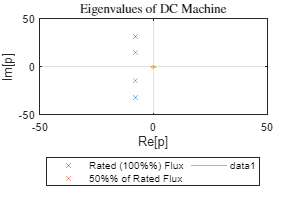

%% Parameter setup
% DC machine Parameters
% Based off a 20hp, 500 rpm DC machine 
Kp_run01 = 4.35;           % machine constant
                           %   (100% rated flux)
Kp_run02 = 0.5*Kp_run01;   % field-weakened machine constant  
                           %   (50% rated flux)
pm_Rp = 1.2*0.168;         % [Ohms] Hot resistance
pm_Lp = 0.013;           % [H] DC machine inductance
pm_Jp = 1.34*1.355;       % [kg*m^2] Moment of inertia
pm_bp = 1e-4;       % [N*m/(rad/s)] Damping coefficient
pm_Ke = Kp_run01;   % [V/(rad/s)] machine constant (BEMF)
pm_Kt = Kp_run01;   % [N*m/A] machine constant (torque)

% Inputs to DC machine 
% (in control theory, the DC machine is known as a "plant" or "process")
Vstep = 5;

% Simulink run parameters
T_duration = 1; % [s] Simulation time 
Ts_sim = 1e-6;  % [s] Sample time


%% RUN #1 in Simulink: Original Parameters
simParam.StartTime = '0';
simParam.StopTime = num2str(T_duration);
simOut = sim('HW_02_DC_Machine_Sim.slx', simParam);
t_sim = simOut.Omega.time';
Omega_sim_run01 = simOut.Omega.data';


%% RUN #2 in Simulink: Field-Weakened Machine
pm_Ke = Kp_run02;   % [V/(rad/s)] machine constant (BEMF)
pm_Kt = Kp_run02;   % [N*m/A] machine constant (torque)
simOut = sim('HW_02_DC_Machine_Sim.slx', simParam);
Omega_sim_run02 = simOut.Omega.data';


%% Plotting
% Eigenvalue plotting
sigma_fullFlux = [real(p1_fullFlux) real(p2_fullFlux)];
omega_d_fullFlux = [imag(p1_fullFlux) imag(p2_fullFlux)];
sigma_halfFlux = [real(p1_halfFlux) real(p2_halfFlux)];
omega_d_halfFlux = [imag(p1_halfFlux) imag(p2_halfFlux)];

figure(31);
plot(sigma_fullFlux, omega_d_fullFlux, ...
    'DisplayName', 'Rated (100%%) Flux', ...
    'Marker','x', 'LineStyle','none'); hold on;
plot(sigma_halfFlux, omega_d_halfFlux, ...
    'DisplayName', '50%% of Rated Flux', ...
    'Marker','x', 'LineStyle','none');
title('Eigenvalues of DC Machine', 'Interpreter', 'Latex')
legend('Location','SouthOutside', 'NumColumns', 2); grid on;
xlim([-50 50])
ylim([-50 50])
ylabel('Im[p]')
xlabel('Re[p]')
grid on;
r = 1;
x = 0;
y = 0;
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
plot(xunit, yunit);
hold off

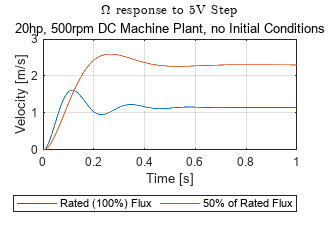


% Simulink plotting
figure;
lgnd_txt = sprintf('Rated (100%%) Flux');
plot(t_sim, Omega_sim_run01, 'DisplayName', lgnd_txt, 'LineWidth', 0.5)
hold on;
lgnd_txt = sprintf('50%% of Rated Flux');
plot(t_sim, Omega_sim_run02, 'DisplayName', lgnd_txt, 'LineWidth', 0.5)
hold off;
title('$\Omega$ response to 5V Step', 'Interpreter', 'Latex')
subtitle('20hp, 500rpm DC Machine Plant, no Initial Conditions')
legend('Location','SouthOutside', 'NumColumns', 2); grid on;
ylabel('Velocity [m/s]')
xlabel('Time [s]')


%%